# Full Wave Simulator

Converts LTSPICE .txt files to a MATLAB Matrix and plots

## Directory and Internal Libraries/Functions

Sets paths easily to run, calling functions that import different data types

computer = "PC";
if (strcmp(computer, 'PC')) % PC 
    %cd 'G:\My Drive\Code\LTSpice\200630 xGAN xGEM Load Responses V0';
    cd 'C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1'
    addpath( 'G:\My Drive\Code\LTSpice\200825 xGAN xGEM Load Responses V1\', ...  % LT Spice output response
             'C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1',...
             'C:\Users\johns\Documents\Github\QEM-MATLAB\Data Converters\LTSpice_Converter', ... % LT Spice reader from Github
             'C:\Users\johns\Documents\Github\QEM-MATLAB', ...    % Access to generic libraries
             'G:\My Drive\Code\COMSOL\xGAN Gated Mirror Sims\Export'); %new comsol stuff
         
elseif (strcmp(computer, 'Mac'))
    %cd 'C:\Users\johns\Documents\Github\QEM-MATLAB\Data Converters\LTSpice_Converter'
    addpath('/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/QEM-MATLAB/Data Converters/LTSpice_Converter', ...
            '/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/QEM-MATLAB', ...
            '/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/Gated-Mirror_xGANxSCAxGEM/200801 xGAN Full Module v1');
end

load('ImpVariables.mat')

## Generate Impedance Response of Load

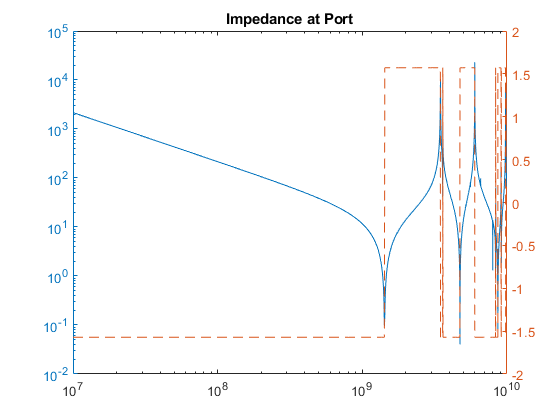

% Workbook for impedance math in "C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1"
% Result is plotted
clf
port = ImportCOMSOL_Z('Kimball_Impedance.txt');
yyaxis left
loglog(port.freq, abs(port.z))
yyaxis right
semilogx(port.freq, unwrap(angle(port.z)),'LineStyle',"--");
title('Impedance at Port')
hold off


ratFitS = rationalfit(port.freq, port.s11);
generateSPICE(ratFitS, 'JWS_TestNetwork_v0.ckt');

## Time Domain Constant step exporter

Takes data from batch files in LTSpice and exports

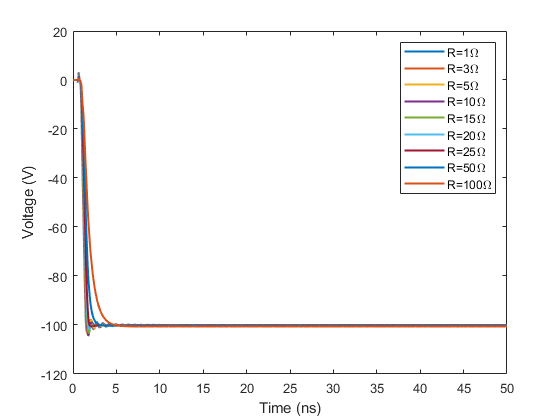

name = '200825 xGAN Kimball Circuit v4.txt';
timeRes = 50E-12; % 20GHz total BW (10Ghz positive)
interpMethod = 'linear'; %pchip linear
[stepR,interpTime, interpVoltAll] = ImportLTSpiceSweep(name, timeRes, interpMethod);

% Plots out result read from file to check
figure()
plot(interpTime/c.nano, interpVoltAll, "LineWidth", 1.5)
xlabel('Time (ns)')
ylabel('Voltage (V)')
rNames = string(stepR);
legend('R=' + rNames +'\Omega')

%xlim ([0,5])


## Symmetrize Outputs for Fourier Analysis and Save

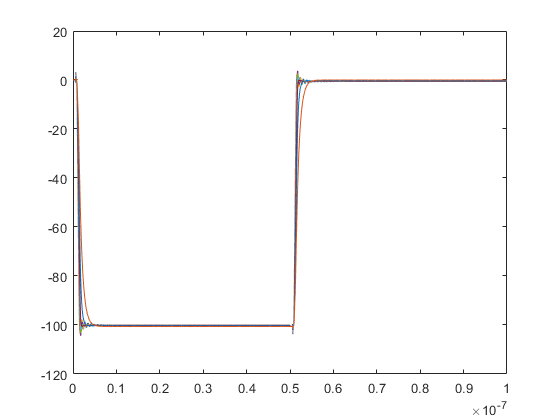

interpVoltAllDbl = [interpVoltAll, interpVoltAll(end)-interpVoltAll(:,2:end)];
interpTimeDbl = [interpTime, interpTime(2:end) + interpTime(end)];
plot(interpTimeDbl,interpVoltAllDbl)


% save symmetrized data
save("200825 xGAN Symmetric Kimball Sweep v4.mat", "stepR", "interpTimeDbl", "interpVoltAllDbl");

## Convert COMSOL Transfer Function 

filename='Kimball_TF.txt';
makeSymmetric = 1;
[rawTF, symTF] = ImportCOMSOL_TF(filename, port.v, makeSymmetric);

comsolFreqStep = 10000000

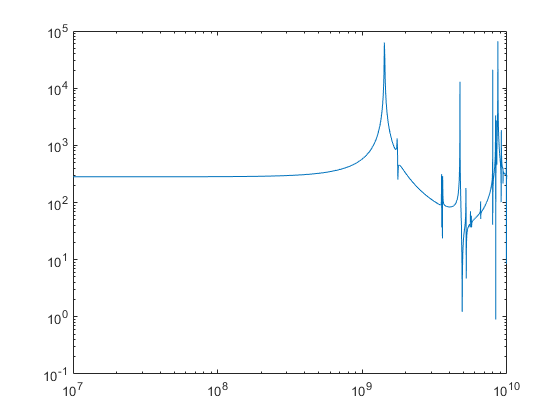


clf;
% Look at transfer Function
loglog(rawTF.freq,abs(rawTF.fieldTF))

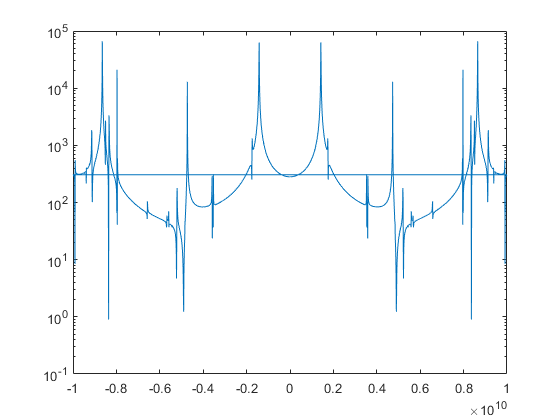


% Check symmetry of fields
semilogy(symTF.freq,abs(symTF.fieldTF))

## Generate and Plot LTSpice Output FT

resIndex = 7;
[time, signal, freq, fftSignal] = dummyFunction('Cos', 0.05*c.nano, 10*c.mega,  interpTimeDbl, interpVoltAllDbl(resIndex,:))

freq = 	1.0e+10 *

   -1.0000   -0.9990   -0.9980   -0.9970   -0.9960   -0.9950   -0.9940   -0.9930   -0.9920   -0.9910   -0.9900   -0.9890   -0.9880   -0.9870   -0.9860   -0.9850   -0.9840   -0.9830   -0.9820   -0.9810   -0.9800   -0.9790   -0.9780   -0.9770   -0.9760   -0.9750   -0.9740   -0.9730   -0.9720   -0.9710   -0.9700   -0.9690   -0.9680   -0.9670   -0.9660   -0.9650   -0.9640   -0.9630   -0.9620   -0.9610   -0.9600   -0.9590   -0.9580   -0.9570   -0.9560   -0.9550   -0.9540   -0.9530   -0.9520   -0.9510


time = 	1.0e+-7 *

   -0.5000   -0.4995   -0.4990   -0.4985   -0.4980   -0.4975   -0.4970   -0.4965   -0.4960   -0.4955   -0.4950   -0.4945   -0.4940   -0.4935   -0.4930   -0.4925   -0.4920   -0.4915   -0.4910   -0.4905   -0.4900   -0.4895   -0.4890   -0.4885   -0.4880   -0.4875   -0.4870   -0.4865   -0.4860   -0.4855   -0.4850   -0.4845   -0.4840   -0.4835   -0.4830   -0.4825   -0.4820   -0.4815   -0.4810   -0.4805   -0.4800   -0.4795   -0.4790   -0.4785   -0.4780   -0.4775   -0.4770   -0.4765   -0.4760   -0.4755


signal =     1.0000    0.9877    0.9511    0.8910    0.8090    0.7071    0.5878    0.4540    0.3090    0.1564    0.0000   -0.1564   -0.3090   -0.4540   -0.5878   -0.7071   -0.8090   -0.8910   -0.9511   -0.9877   -1.0000   -0.9877   -0.9511   -0.8910   -0.8090   -0.7071   -0.5878   -0.4540   -0.3090   -0.1564    0.0000    0.1564    0.3090    0.4540    0.5878    0.7071    0.8090    0.8910    0.9511    0.9877    1.0000    0.9877    0.9511    0.8910    0.8090    0.7071    0.5878    0.4540    0.3090    0.1564


freq = 	1.0e+10 *

   -1.0000   -0.9990   -0.9980   -0.9970   -0.9960   -0.9950   -0.9940   -0.9930   -0.9920   -0.9910   -0.9900   -0.9890   -0.9880   -0.9870   -0.9860   -0.9850   -0.9840   -0.9830   -0.9820   -0.9810   -0.9800   -0.9790   -0.9780   -0.9770   -0.9760   -0.9750   -0.9740   -0.9730   -0.9720   -0.9710   -0.9700   -0.9690   -0.9680   -0.9670   -0.9660   -0.9650   -0.9640   -0.9630   -0.9620   -0.9610   -0.9600   -0.9590   -0.9580   -0.9570   -0.9560   -0.9550   -0.9540   -0.9530   -0.9520   -0.9510


fftSignal = 0

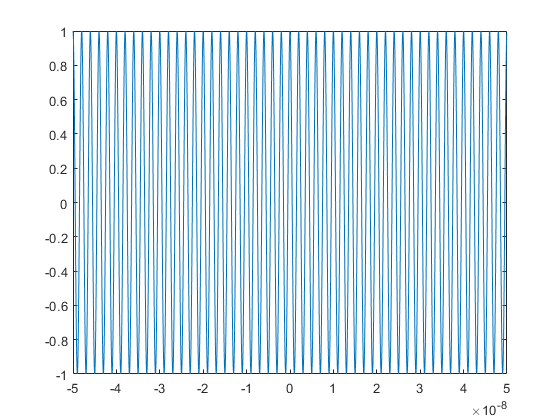

plot(time, signal)

## Generate Fourier Transform of LTSpice Output

workspaceName='200825 xGAN Symmetric Kimball Sweep v4.mat';
load(workspaceName);
r=7;%which damping resistor 
vLoadRaw=transpose(interpVoltAllDbl(r,:));
timeRaw=transpose(interpTimeDbl);
% time=downsample(timeRaw,5);
% vLoad=downsample(vLoadRaw,5);
time=decimate(timeRaw,7);
vLoad=decimate(vLoadRaw,7);

T=mean(diff(time)); %time iterations
BW=1/(2*T);
Fs=1/T; %sampling frequency
L=length(time);
padLength=floor(L/2)*100;
[trash,midVidx]=min(abs(vLoad-mean(vLoad)));
shift=floor(L/2)-midVidx;
padFront=vLoad(1)*ones(shift+padLength/2,1);
padEnd=vLoad(end)*ones(-shift+padLength/2,1);
vLoadPad=[padFront;vLoad;padEnd];
timePad=T*transpose(0:length(vLoadPad)-1);
Lpad=length(timePad);
fPos=(0:(Lpad/2-1))*(Fs/Lpad);
fNeg=((-Lpad/2):-1)*(Fs/Lpad);
f=transpose([0:Lpad/2-1, -Lpad/2:-1]*(Fs/Lpad));
vLoadTF=fft(vLoadPad,length(f));

## Extra Functions

if(0) % shuts off everything below here

## Code from GitHub

[https://github.com/PeterFeicht/ltspice2matlab.git](https://github.com/PeterFeicht/ltspice2matlab.git)

% Very nice converter from Github!!

% !!!!!!!!!!! Can NOT do steps.. sadly !!!!!!!!!!

addpath('C:\Users\johns\Documents\Github\ltspice2matlab') 
addpath('G:\My Drive\Code\LTSpice\200630 xGAN xGEM Load Responses V0')
% function raw_data = LTspice2Matlab( filename, varargin )
%    Calling Convention:
%        RAW_DATA = LTspice2Matlab( FILENAME );                  % Returns all variables found in FILENAME
%                             (or)
%        RAW_DATA = LTspice2Matlab( FILENAME, SELECTED_VARS );   % Returns only selected variables
%               Set SELECTED_VARS to [] to quickly determine the number and names of variables present in
%               FILENAME without actually loading the variables.
%                             (or)
%        RAW_DATA = LTspice2Matlab( FILENAME, SELECTED_VARS, N );
%               Returns variables listed in SELECTED_VARS, with all waveforms downsampled by N. Set N > 1 to
%               load very large data files using less memory, at the price of degraded waveform accuracy and
%               possible aliasing.

filename = '200728 xGAN Kimball Circuit v1.raw'
% rawData = LTspice2Matlab( filename, [] )

rawData = LTspice2Matlab( filename, [10])

rawData.variable_name_list % V(n005) is column 10

time = rawData.time_vect;
voltage = rawData.variable_mat;
plot(time, voltage)

% R = 20;
% RString = num2str(R);
% saveName = "KimbalDampingR" + RString +'.mat';
% save(saveName, 'time', 'voltage')

## Interpolate to constant time step!

% timeRes = 10E-12; % 10ps time resolution
% interpTime = linspace(time(1), time(end), (time(end)-time(1))/timeRes+1);
% interpVolt = interp1(time,voltage,interpTime, 'PCHIP');
% 
% figure(2)
% titleText = ['Interpolated File ', name];
% plot(interpTime, interpVolt);
% title(titleText);
% xlabel(tit1);
% ylabel(tit2);


## Original Method Direct Read

% % Checks data from current directory with frequency data 
% Files = dir;
% checkThis = 2; % which file to read/look at
% name = Files(checkThis).name;
% 
% fileID = fopen(name,'rt');
% formatSpec = '%f\t%f';
% 
% %A = fscanf(fileID,formatSpec)
% titles = textscan(fileID, '%s\t%s', 1);
% data = textscan(fileID, formatSpec);
% tit1 = titles{1};
% tit2 = titles{2};
% tit1 = tit1{1};
% tit2 = tit2{1};
% 
% time = data(1);
% voltage = data(2);
% time = time{1}';
% voltage = voltage{1}.';
% 
% fclose(fileID);
% 
% figure(1)
% titleText = ['File ', name];
% plot(time, voltage);
% title(titleText);
% xlabel(tit1);
% ylabel(tit2);
% 


## Frequency Plotters and Extractor

This section converts LTSpice frequency domain outputs to MATLAB and plots them. It takes exported waveforms as such:

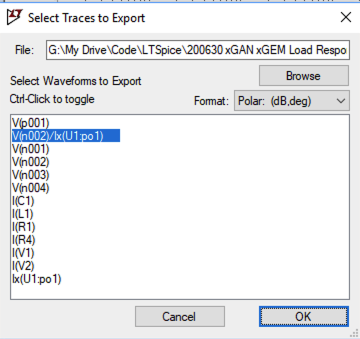

With outputs like this: 

First Line do: "Freq.	V(n002)/Ix(U1:po1)"

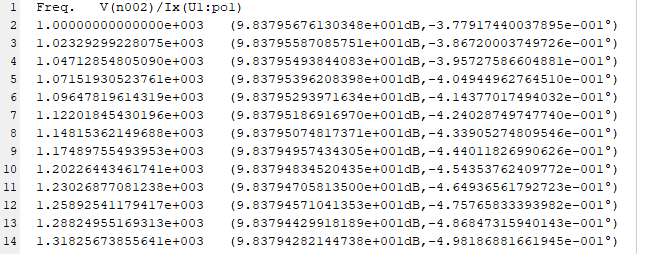

And plots it for us in MATLAB

filenameAdd = '200701 xGAN xGEM Freq Response.txt';
% Single line version exports just raw frequency respnse
% !!!!!!! Must replace top line with 'Freq.	V(n002)/Ix(U1:po1)' !!!!!!!!!
    Data = LT_Freq2Table(filenameAdd)
    % Data = table2array(Data);
    freq = Data(:,'Freq');
    MagZ_out_dB = Data(:,'n002');
    AngZ_out = Data(:,'U1po1');
    freq = table2array(freq);
    MagZ_out_dB = table2array(MagZ_out_dB);
    AngZ_out = table2array(AngZ_out);
    MagZ_out = 10.^(MagZ_out_dB/20)
    
    loglog(freq, (MagZ_out))
    
    samplePt = 1001; %pt 1001 = 100MHz = 124.78298 ohm directly
    freqSample = freq(samplePt)
    zSample = MagZ_out(samplePt) % convert from dB to normal!s
    % z = 1/(2pi*f*C)lead to
    C_eff = 1/(2*pi*freqSample*abs(zSample))
    
    resFreq = 1.0694652e9; %GHz
    % w^2 = 1/LC
    L_eff = 1/((2*pi*resFreq)^2*C_eff)
    save('200701 xGAN Kimball RLC Full Freq Resp', 'freq', 'MagZ_out')


end